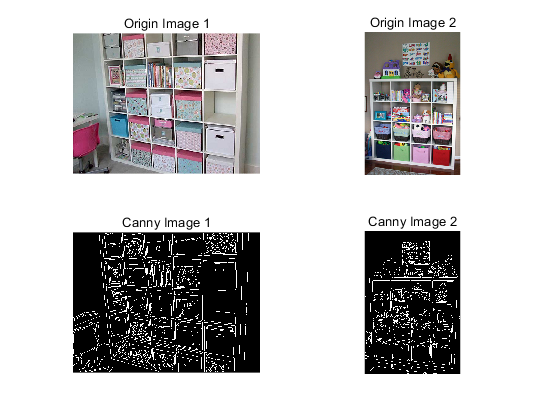

% KAIST EE667
% Multiple View Geometry, 2021 Spring
% HW1: Image Rectification 
%
% Student ID     : 20213569
% Name           : Byeongin Joung
% Date           : 2021.03.18
% Matlab Ver.    : R2021a
%

% Problem 1: Two-step Recitification

% Load RGB Images
img1 = imread('HW1_20213569_1.jpg');
img2 = imread('HW1_20213569_2.jpg');

% Transform to gray-scale images
img1_gray = rgb2gray(img1);
img2_gray = rgb2gray(img2);

% To find parallel lines in the image, use hough transform
% which is supported by "Image Processing Toolbox"
% Image Processing Toolbox link: https://kr.mathworks.com/help/images/index.html?s_tid=CRUX_lftnav

% To get hough lines, get binary image.
BW1 = edge(img1_gray, 'canny');
BW2 = edge(img2_gray, 'canny');

figure
subplot(2,2,1), imshow(img1), title('Origin Image 1')
subplot(2,2,2), imshow(img2), title('Origin Image 2')
subplot(2,2,3), imshow(BW1), title('Canny Image 1')
subplot(2,2,4), imshow(BW2), title('Canny Image 2')

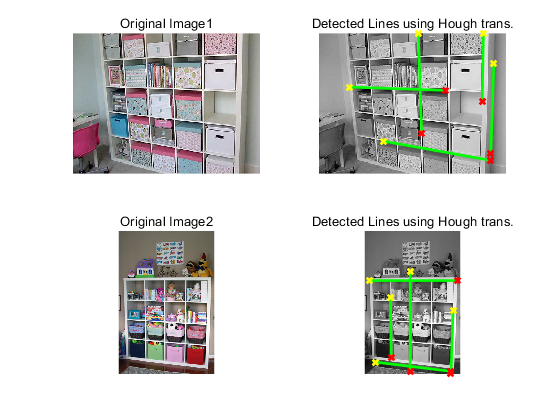


% Using hough, find peak points
[H1, T1, R1] = hough(BW1);
[H2, T2, R2] = hough(BW2);
P1 = houghpeaks(H1, 5, 'threshold', ceil(0.3*max(H1(:))));
P2 = houghpeaks(H2, 5, 'threshold', ceil(0.3*max(H2(:))));

% find lines
lines1 = houghlines(BW1, T1, R1, P1, 'FillGap', 15, 'MinLength', 100);
lines2 = houghlines(BW2, T2, R2, P2, 'FillGap', 15, 'MinLength', 200);

% Visualize loaded images and detected lines in their gray-scale
figure

subplot(2,2,1), imshow(img1), title('Original Image1')
subplot(2,2,2), imshow(img1_gray), hold on
for k = 1:length(lines1)
    xy = [lines1(k).point1; lines1(k).point2];
    plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
    plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
    plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
end
title('Detected Lines using Hough trans.')
subplot(2,2,3), imshow(img2), title('Original Image2')

subplot(2,2,4), imshow(img2_gray), hold on
for k = 1:length(lines2)
    xy = [lines2(k).point1; lines2(k).point2];
    plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
    plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
    plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
end
title('Detected Lines using Hough trans.')

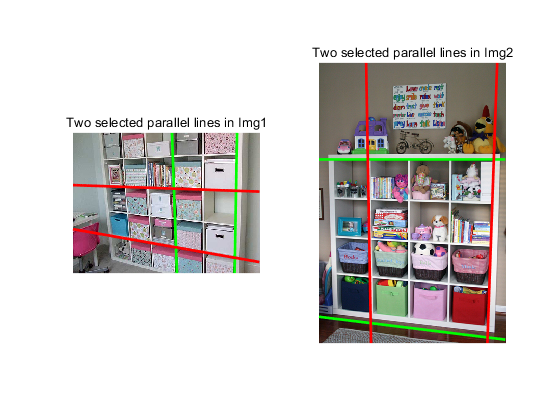

% Find profer line to use (this work might be required some time)
% and get components of parallel lines at each image

% Draw full line for that and find which points are on that lines
% NOTE: (0,0) is left-top point of image

% To prepare the case of that the results are shown different,
% This is list for my case. (check variable "lines1" and "lines2")
% (If the content of report is different from matlab, please use below content)
% ----------------------------------------------------------------------------
% |               1st Image             |                2nd Image            |
% ----------------------------------------------------------------------------
% |      coordinate      | theta |  rho |       coordinate     | theta |  rho |
% ----------------------------------------------------------------------------
% |                                   green                                   |
% ----------------------------------------------------------------------------
% | (266,  2), (275,268) |   -2  |  265 | ( 19,191), (356,191) |  -90  | -190 |
% ----------------------------------------------------------------------------
% | (440,  2), (437,183) |    1  |  439 | ( 43,505), (331,540) |  -83  | -495 |
% ----------------------------------------------------------------------------
% |                                    red                                    |
% ----------------------------------------------------------------------------
% | ( 82,144), (338,153) |  -88  | -140 | ( 99,258), (102,487) |   -1  |   93 | 
% ----------------------------------------------------------------------------
% | (174,289), (459,340) |  -80  | -254 | (340,308), (332,549) |    2  |  350 |
% ----------------------------------------------------------------------------

% Initialize Line
% red_l   : [2 red lines in 1st image  , 2 red lines in 2nd image  ]
% green_l : [2 green lines in 1st image, 2 green lines in 2nd image]

% Find Lines
% l = [a, b, c], then ax + by + c = 0
red_l = zeros(4, 3);
green_l = zeros(4, 3);
index = 1;

figure

% For 1st image, 3rd and 5th lines are proper lines for HW
subplot(1, 2, 1), imshow(img1), hold on
x1_plot_origin = size(img1, 2);
x1_origin = linspace(0,x1_plot_origin-1,x1_plot_origin);
for k = [1 5]
    y = (lines1(k).rho - x1_origin * cosd(lines1(k).theta))/sind(lines1(k).theta);
    plot(x1_origin,y,'LineWidth',2,'Color','green');
    green_l(index,1) = cosd(lines1(k).theta);
    green_l(index,2) = sind(lines1(k).theta);
    green_l(index,3) = -lines1(k).rho;
    index = index + 1;
end

index = 1;
for k = [2 4]
    y = (lines1(k).rho - x1_origin * cosd(lines1(k).theta))/sind(lines1(k).theta);
    plot(x1_origin,y,'LineWidth',2,'Color','red');
    red_l(index,1) = cosd(lines1(k).theta);
    red_l(index,2) = sind(lines1(k).theta);
    red_l(index,3) = -lines1(k).rho;
    index = index + 1;
end
title('Two selected parallel lines in Img1')

% For 2nd image, 5th and 6th lines are proper lines for HW
subplot(1,2,2), imshow(img2), hold on
x2_plot_origin = size(img2, 2);
x2_origin = linspace(0,x2_plot_origin-1,x2_plot_origin);
for k = [2 5]
    y = (lines2(k).rho - x2_origin * cosd(lines2(k).theta))/sind(lines2(k).theta);
    plot(x2_origin,y,'LineWidth',2,'Color','green');
    green_l(index,1) = cosd(lines2(k).theta);
    green_l(index,2) = sind(lines2(k).theta);
    green_l(index,3) = -lines2(k).rho;
    index = index + 1;
end
index = 3;
for k = [3 4]
    y = (lines2(k).rho - x2_origin * cosd(lines2(k).theta))/sind(lines2(k).theta);
    plot(x2_origin,y,'LineWidth',2,'Color','red');
    red_l(index,1) = cosd(lines2(k).theta);
    red_l(index,2) = sind(lines2(k).theta);
    red_l(index,3) = -lines2(k).rho;
    index = index + 1;
end
title('Two selected parallel lines in Img2')

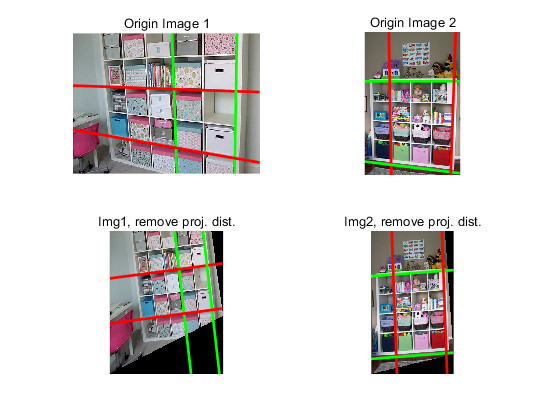

% Find vanishing points
vp1_green = cross(green_l(1, 1:3), green_l(2, 1:3));
vp2_green = cross(green_l(3, 1:3), green_l(4, 1:3));
vp1_red = cross(red_l(1, 1:3), red_l(2, 1:3));
vp2_red = cross(red_l(3, 1:3), red_l(4, 1:3));

% Up-scaling
vp1_green = 1/vp1_green(3)*vp1_green;
vp2_green = 1/vp2_green(3)*vp2_green;
vp1_red = 1/vp1_red(3)*vp1_red;
vp2_red = 1/vp2_red(3)*vp2_red;

% Find line of infinite
loi1 = cross(vp1_green, vp1_red);
loi1 = loi1/(loi1(3));
loi2 = cross(vp2_green, vp2_red);
loi2 = loi2/(loi2(3));

% Find the projective matrix
H_p1 = [1 0 0; 0 1 0; loi1(1) loi1(2) loi1(3)];
H_p2 = [1 0 0; 0 1 0; loi2(1) loi2(2) loi2(3)];

% Get projected lines
glp = green_l;
rlp = red_l;

for k = [1 2 3 4]
    if k == 1 || k == 2
        glp(k,1:3) = transpose(H_p1)\transpose(green_l(k,1:3));
        rlp(k,1:3) = transpose(H_p1)\transpose(red_l(k,1:3));
    else
        glp(k,1:3) = transpose(H_p2)\transpose(green_l(k,1:3));
        rlp(k,1:3) = transpose(H_p2)\transpose(red_l(k,1:3));
    end
end

% Using projective matrix, remove projective distortion
proj_img1 = imwarp(img1, projective2d(transpose(H_p1)));
proj_img2 = imwarp(img2, projective2d(transpose(H_p2)));

figure
subplot(2,2,1), imshow(img1), title('Origin Image 1'), hold on
for k = [1 2] % draw lines
    y = (-green_l(k,3) - x1_origin * green_l(k,1))/green_l(k,2);
    plot(x1_origin,y, 'LineWidth', 2, 'Color', 'green');
    y = (-red_l(k,3) - x1_origin * red_l(k,1))/red_l(k,2);
    plot(x1_origin,y, 'LineWidth', 2, 'Color', 'red');
end

subplot(2,2,2), imshow(img2), title('Origin Image 2'), hold on
for k = [3 4] % draw lines
    y = (-green_l(k,3) - x2_origin * green_l(k,1))/green_l(k,2);
    plot(x2_origin,y, 'LineWidth', 2, 'Color', 'green');
    y = (-red_l(k,3) - x2_origin * red_l(k,1))/red_l(k,2);
    plot(x2_origin,y, 'LineWidth', 2, 'Color', 'red');
end

subplot(2,2,3), imshow(proj_img1), hold on
x1_plot_proj = size(proj_img1, 2);
x1_proj = linspace(0,x1_plot_proj-1,x1_plot_proj);
for k = [1 2] % draw lines
    y = (-glp(k,3) - x1_proj * glp(k,1))/glp(k,2);
    plot(x1_proj,y, 'LineWidth', 2, 'Color', 'green');
    y = (-rlp(k,3) - x1_proj * rlp(k,1))/rlp(k,2);
    plot(x1_proj,y, 'LineWidth', 2, 'Color', 'red');
end
title('Img1, remove proj. dist.')

subplot(2,2,4), imshow(proj_img2), hold on
x2_plot_proj = size(proj_img2, 2);
x2_proj = linspace(0,x2_plot_proj-1,x2_plot_proj);
for k = [3 4] % draw lines
    y = (-glp(k,3) - x2_proj * glp(k,1))/glp(k,2);
    plot(x2_proj,y, 'LineWidth', 2, 'Color', 'green');
    y = (-rlp(k,3) - x2_proj * rlp(k,1))/rlp(k,2);
    plot(x2_proj,y, 'LineWidth', 2, 'Color', 'red');
end
title('Img2, remove proj. dist.')

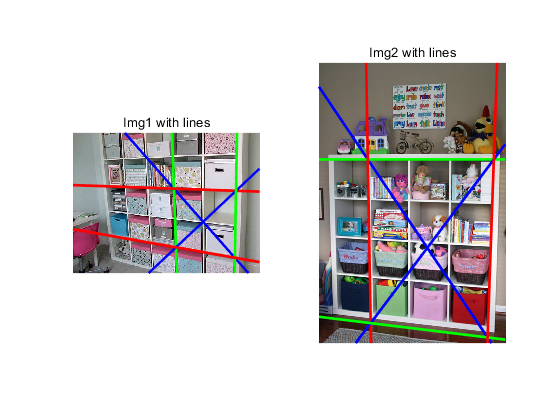

% Using affine matrix, remove affine distortion

% Find the other orthogonal line
vp_gr1 = ones(4, 3);
vp_gr2 = ones(4, 3);

for k = [1 2 3 4]
    vp_gr1(k,1:3) = cross(green_l(k,1:3), red_l(k,1:3));
end

for k = [1 2 3 4]
    if k == 1 || k == 3
        vp_gr2(k,1:3) = cross(green_l(k,1:3), red_l(k+1,1:3));
    else
        vp_gr2(k,1:3) = cross(green_l(k,1:3), red_l(k-1,1:3));
    end
end

% get the other orthogonal line
blue_l = ones(4,3);
blue_l(1,1:3) = cross(vp_gr1(1,1:3), vp_gr1(2, 1:3));
blue_l(2,1:3) = cross(vp_gr2(1,1:3), vp_gr2(2, 1:3));
blue_l(3,1:3) = cross(vp_gr1(3,1:3), vp_gr1(4, 1:3));
blue_l(4,1:3) = cross(vp_gr2(3,1:3), vp_gr2(4, 1:3));

figure
subplot(1,2,1), imshow(img1), title('Img1 with lines'), hold on
for k = [1 2] % draw lines
    y = (-blue_l(k,3) - x1_origin * blue_l(k,1))/blue_l(k,2);
    plot(x1_origin,y, 'LineWidth', 2, 'Color', 'blue');
    y = (-green_l(k,3) - x1_origin * green_l(k,1))/green_l(k,2);
    plot(x1_origin,y, 'LineWidth', 2, 'Color', 'green');
    y = (-red_l(k,3) - x1_origin * red_l(k,1))/red_l(k,2);
    plot(x1_origin,y, 'LineWidth', 2, 'Color', 'red');
end

subplot(1,2,2), imshow(img2), title('Img2 with lines'), hold on
for k = [3 4] % draw lines
    y = (-blue_l(k,3) - x2_origin * blue_l(k,1))/blue_l(k,2);
    plot(x2_origin,y, 'LineWidth', 2, 'Color', 'blue');
    y = (-green_l(k,3) - x2_origin * green_l(k,1))/green_l(k,2);
    plot(x2_origin,y, 'LineWidth', 2, 'Color', 'green');
    y = (-red_l(k,3) - x2_origin * red_l(k,1))/red_l(k,2);
    plot(x2_origin,y, 'LineWidth', 2, 'Color', 'red');
end

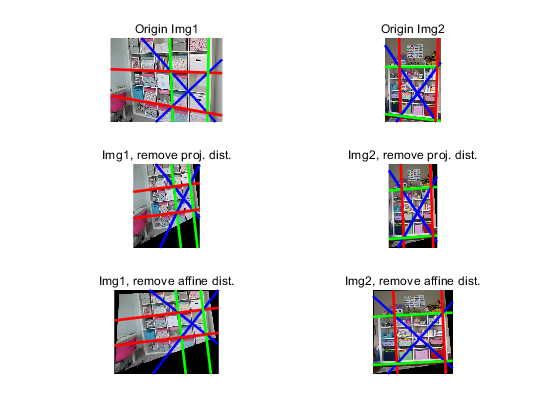


% Using new orthogonal line, find affine matrix

% Get projected lines
blp = ones(4,3);

for k = [1 2 3 4]
    if k == 1 || k == 2
        blp(k,1:3) = transpose(H_p1)\transpose(blue_l(k,1:3));
    else
        blp(k,1:3) = transpose(H_p2)\transpose(blue_l(k,1:3));
    end
end

% Find S using formula
mat11 = [glp(1,1)*rlp(2,1) glp(1,1)*rlp(2,2)+glp(1,2)*rlp(2,1); ...
        blp(1,1)*blp(2,1) blp(1,1)*blp(2,2)+blp(1,2)*blp(2,1)];
mat12 = [-glp(1,2)*rlp(2,2); -blp(1,2)*blp(2,2)];

mat21 = [glp(3,1)*rlp(3,1) glp(3,1)*rlp(3,2)+glp(3,2)*rlp(3,1); ...
        blp(3,1)*blp(4,1) blp(3,1)*blp(4,2)+blp(3,2)*blp(4,1)];
mat22 = [-glp(3,2)*rlp(3,2); -blp(3,2)*blp(4,2)];

s1 = mat11\mat12;
s2 = mat21\mat22;

S1 = [s1(1) s1(2); s1(2) 1];
S2 = [s2(1) s2(2); s2(2) 1];

[U1, D1, V1] = svd(S1);
[U2, D2, V2] = svd(S2);

A1 = U1*sqrt(D1)*V1;
A2 = U2*sqrt(D2)*V2;

affineMat1 = inv([A1(1,1) A1(1,2) 0; A1(2,1) A1(2,2) 0; 0 0 1]);
affineMat2 = inv([A2(1,1) A2(1,2) 0; A2(2,1) A2(2,2) 0; 0 0 1]);

affine_img1 = imwarp(proj_img1, affine2d(affineMat1));
affine_img2 = imwarp(proj_img2, affine2d(affineMat2));

% Calculate moved distance of origin to align lines on image
% this values will be leveraged as :
%    y = (-c - (x + ml)*b)/a - mr
mo = ones(4,3);
ml = ones(4,3);
mr = ones(4,3);

mo(1,1:3) = transpose(affineMat1)*[1;1;1];
ml(1,1:3) = transpose(affineMat1)*[1;size(proj_img1,1);1];
mr(1,1:3) = transpose(affineMat1)*[size(proj_img1,2);1;1];

mo(2,1:3) = transpose(affineMat2)*[1;1;1];
ml(2,1:3) = transpose(affineMat2)*[1;size(proj_img2,1);1];
mr(2,1:3) = transpose(affineMat2)*[size(proj_img2,2);1;1];

% Get lines
for k = [1 2 3 4]
    if k == 1 || k == 2
        gla(k,1:3) = transpose(affineMat1)\transpose(glp(k,1:3));
        rla(k,1:3) = transpose(affineMat1)\transpose(rlp(k,1:3));
        bla(k,1:3) = transpose(affineMat1)\transpose(blp(k,1:3));
    else
        gla(k,1:3) = transpose(affineMat2)\transpose(glp(k,1:3));
        rla(k,1:3) = transpose(affineMat2)\transpose(rlp(k,1:3));
        bla(k,1:3) = transpose(affineMat2)\transpose(blp(k,1:3));
    end
end

figure % plot all images
subplot(3,2,1), imshow(img1), title('Origin Img1'), hold on
for k = [1 2] % draw lines
    y = (-blue_l(k,3) - x1_origin * blue_l(k,1))/blue_l(k,2);
    plot(x1_origin,y, 'LineWidth', 2, 'Color', 'blue');
    y = (-green_l(k,3) - x1_origin * green_l(k,1))/green_l(k,2);
    plot(x1_origin,y, 'LineWidth', 2, 'Color', 'green');
    y = (-red_l(k,3) - x1_origin * red_l(k,1))/red_l(k,2);
    plot(x1_origin,y, 'LineWidth', 2, 'Color', 'red');
end

subplot(3,2,2), imshow(img2), title('Origin Img2'), hold on
for k = [3 4] % draw lines
    y = (-blue_l(k,3) - x2_origin * blue_l(k,1))/blue_l(k,2);
    plot(x2_origin,y, 'LineWidth', 2, 'Color', 'blue');
    y = (-green_l(k,3) - x2_origin * green_l(k,1))/green_l(k,2);
    plot(x2_origin,y, 'LineWidth', 2, 'Color', 'green');
    y = (-red_l(k,3) - x2_origin * red_l(k,1))/red_l(k,2);
    plot(x2_origin,y, 'LineWidth', 2, 'Color', 'red');
end

subplot(3,2,3), imshow(proj_img1), hold on
for k = [1 2]
    y = (-blp(k,3) - x1_proj * blp(k,1))/blp(k,2);
    plot(x1_proj,y, 'LineWidth', 2, 'Color', 'blue');
    y = (-glp(k,3) - x1_proj * glp(k,1))/glp(k,2);
    plot(x1_proj,y, 'LineWidth', 2, 'Color', 'green');
    y = (-rlp(k,3) - x1_proj * rlp(k,1))/rlp(k,2);
    plot(x1_proj,y, 'LineWidth', 2, 'Color', 'red');
end
title('Img1, remove proj. dist.')

subplot(3,2,4), imshow(proj_img2), hold on
for k = [3 4]
    y = (-blp(k,3) - x2_proj * blp(k,1))/blp(k,2);
    plot(x2_proj,y, 'LineWidth', 2, 'Color', 'blue');
    y = (-glp(k,3) - x2_proj * glp(k,1))/glp(k,2);
    plot(x2_proj,y, 'LineWidth', 2, 'Color', 'green');
    y = (-rlp(k,3) - x2_proj * rlp(k,1))/rlp(k,2);
    plot(x2_proj,y, 'LineWidth', 2, 'Color', 'red');
end
title('Img2, remove proj. dist.')

subplot(3,2,5), imshow(affine_img1), hold on
x1_plot_affine = size(affine_img1, 2);
x1_affine = linspace(0, x1_plot_affine-1, x1_plot_affine);
for k = [1 2]
    y = (-bla(k,3) - (x1_affine + ml(1,1)) * bla(k,1))/bla(k,2) - mr(1,2);
    plot(x1_affine,y, 'LineWidth', 2, 'Color', 'blue');
    y = (-gla(k,3) - (x1_affine + ml(1,1)) * gla(k,1))/gla(k,2) - mr(1,2);
    plot(x1_affine,y, 'LineWidth', 2, 'Color', 'green');
    y = (-rla(k,3) - (x1_affine + ml(1,1)) * rla(k,1))/rla(k,2) - mr(1,2);
    plot(x1_affine,y, 'LineWidth', 2, 'Color', 'red');
end
title('Img1, remove affine dist.')

subplot(3,2,6), imshow(affine_img2), hold on
x2_plot_affine = size(affine_img2, 2);
x2_affine = linspace(0, x2_plot_affine-1, x2_plot_affine);
for k = [3 4]
    y = (-bla(k,3) - (x2_affine + ml(2,1)) * bla(k,1))/bla(k,2) - mr(2,2);
    plot(x2_affine,y, 'LineWidth', 2, 'Color', 'blue');
    y = (-gla(k,3) - (x2_affine + ml(2,1)) * gla(k,1))/gla(k,2) - mr(2,2);
    plot(x2_affine,y, 'LineWidth', 2, 'Color', 'green');
    y = (-rla(k,3) - (x2_affine + ml(2,1)) * rla(k,1))/rla(k,2) - mr(2,2);
    plot(x2_affine,y, 'LineWidth', 2, 'Color', 'red');
end
title('Img2, remove affine dist.')

% Problem 2: One-step Recitification

% Using Dual Conic, remove affine distortion

% Normalize each lines
for k = [1 2 3 4]
    green_l(k,1:3) = green_l(k,1:3)/green_l(k,3);
    red_l(k,1:3) = red_l(k,1:3)/red_l(k,3);
    blue_l(k,1:3) = blue_l(k,1:3)/blue_l(k,3);
end
 
% Get Dual conic
DC_Mat1 = utils.getConic(1, green_l, red_l, blue_l);

이름 utils.getConic을(를) 확인할 수 없습니다.

DC_Mat2 = utils.getConic(3, green_l, red_l, blue_l);
 
% Get a, b, c, d, e
c1 = DC_Mat1\[-1;-1;-1;-1;-1];
c2 = DC_Mat2\[-1;-1;-1;-1;-1];

C_inf_star1 = [c1(1) c1(2)/2 c1(4)/2;
               c1(2)/2 c1(3) c1(5)/2;
               c1(4)/2 c1(5)/2 1 ];

C_inf_star2 = [c2(1) c2(2)/2 c2(4)/2;
               c2(2)/2 c2(3) c2(5)/2;
               c2(4)/2 c2(5)/2 1 ];
 
[U3, D3, V3] = svd(C_inf_star1);
[U4, D4, V4] = svd(C_inf_star2);
 
% eigenvalues of C_inf_star# are located in S3 and S4 repectively
H3 = U3*sqrt(D3);
H4 = U4*sqrt(D4);

% normalize H3 and H4
H3 = H3/H3(2,1);
H4 = H4/H4(2,1);
H3(3,3) = 1;
H4(3,3) = 1;

% Get inverse of H and rectified image by using imwarp
H3 = inv(H3);
H4 = inv(H4);

affine_img1_DC = imwarp(img1, projective2d(transpose(H3)));
affine_img2_DC = imwarp(img2, projective2d(transpose(H4)));
 
% Get distorted distance and align lines on each images
% mrl : indicates right bottom of image
% At this time, mrl value is needed to align lines
mrl = ones(2,3);

mo(3,1:3) = (H3)*[1;1;1];
ml(3,1:3) = (H3)*[1;size(img1,1);1];
mr(3,1:3) = (H3)*[size(img1,2);1;1];
mrl(1,1:3) = (H3)*[size(img1,2);size(img1,1);1];
ml(3,1:3) = ml(3,1:3)/ml(3,3);
mr(3,1:3) = mr(3,1:3)/mr(3,3);
mrl(1,1:3) = mrl(1,1:3)/mrl(1,3);

mo(4,1:3) = (H4)*[1;1;1];
ml(4,1:3) = (H4)*[1;size(img2,1);1];
mr(4,1:3) = (H4)*[size(img2,2);1;1];
mrl(2,1:3) = (H4)*[size(img2,2);size(img2,1);1];
ml(4,1:3) = ml(4,1:3)/ml(4,3);
mr(4,1:3) = mr(4,1:3)/mr(4,3);
mrl(2,1:3) = mrl(2,1:3)/mrl(2,3);

% Get lines
for k = [1 2 3 4]
    if k == 1 || k == 2
        glc(k,1:3) = transpose(H3)\transpose(green_l(k,1:3));
        rlc(k,1:3) = transpose(H3)\transpose(red_l(k,1:3));
        blc(k,1:3) = transpose(H3)\transpose(blue_l(k,1:3));
    else
        glc(k,1:3) = transpose(H4)\transpose(green_l(k,1:3));
        rlc(k,1:3) = transpose(H4)\transpose(red_l(k,1:3));
        blc(k,1:3) = transpose(H4)\transpose(blue_l(k,1:3));
    end
end

figure
subplot(2,2,1), imshow(img1), title('Origin Img1'), hold on
for k = [1 2] % draw lines
    y = (-blue_l(k,3) - x1_origin * blue_l(k,1))/blue_l(k,2);
    plot(x1_origin,y, 'LineWidth', 2, 'Color', 'blue');
    y = (-green_l(k,3) - x1_origin * green_l(k,1))/green_l(k,2);
    plot(x1_origin,y, 'LineWidth', 2, 'Color', 'green');
    y = (-red_l(k,3) - x1_origin * red_l(k,1))/red_l(k,2);
    plot(x1_origin,y, 'LineWidth', 2, 'Color', 'red');
end

subplot(2,2,2), imshow(img2), title('Origin Img2'), hold on
for k = [3 4] % draw lines
    y = (-blue_l(k,3) - x2_origin * blue_l(k,1))/blue_l(k,2);
    plot(x2_origin,y, 'LineWidth', 2, 'Color', 'blue');
    y = (-green_l(k,3) - x2_origin * green_l(k,1))/green_l(k,2);
    plot(x2_origin,y, 'LineWidth', 2, 'Color', 'green');
    y = (-red_l(k,3) - x2_origin * red_l(k,1))/red_l(k,2);
    plot(x2_origin,y, 'LineWidth', 2, 'Color', 'red');
end

subplot(2,2,3), imshow(affine_img1_DC), hold on
x1_plot = size(affine_img1_DC, 2);
x = linspace(0, x1_plot-1, x1_plot); % x = 0 ~ 442
for k = [1 2]
    y = (-blc(k,3) - x * blc(k,1))/blc(k,2) - mrl(1,2);
    plot(x,y, 'LineWidth', 2, 'Color', 'blue');
    y = (-glc(k,3) - x * glc(k,1))/glc(k,2) - mrl(1,2);
    plot(x,y, 'LineWidth', 2, 'Color', 'green');
    y = (-rlc(k,3) - x * rlc(k,1))/rlc(k,2) - mrl(1,2);
    plot(x,y, 'LineWidth', 2, 'Color', 'red');
end
title('Img1, remove affine dist.')

subplot(2,2,4), imshow(affine_img2_DC), hold on
x2_plot = size(affine_img2_DC, 2);
x = linspace(0, x2_plot-1, x2_plot); % x = 0 ~ 624
for k = [3 4]
    y = (-blc(k,3) - x * blc(k,1))/blc(k,2) - mrl(2,2);
    plot(x,y, 'LineWidth', 2, 'Color', 'blue');
    y = (-glc(k,3) - x * glc(k,1))/glc(k,2) - mrl(2,2);
    plot(x,y, 'LineWidth', 2, 'Color', 'green');
    y = (-rlc(k,3) - x * rlc(k,1))/rlc(k,2) - mrl(2,2);
    plot(x,y, 'LineWidth', 2, 'Color', 'red');
end
title('Img2, remove affine dist.')